# **Lab 3. Polarization of ARX estimators**

Through this lab we will demonstrate the problem of the polarization of the estimation error of the vector of the parameters. We will show that, when an ARX model is identified with a model belonging to an ARX family, the error decreases as the number of data increases; when the noise model is uncorrect (for example when using an ARMAX family), the ARX estimator is evidently polarized. 

## 1. Identifying a system with the wrong model

Let's start by identifying an ARMAX system with an ARX model, so with the wrong model.

clc, clearvars, close all

Since we are working with random values, we use a `for` loop over a certain number of itertions in order to stabilize the noise.

% Initialization
errors = [];

% Loop
for i=1:20

### 1.1. Defining the system

We first define three vectors for the polynomials `A`, `B` and `C` of the ARMAX model.

    % ARMAX polynomials
    A = [1.00, -2.61,  2.49, -1.02, 0.15];
    B = [0.00, -0.02, -0.03,  0.05, 0.01];
    C = [1.00,  1.90,  0.04];

Then we choose the sampling time and the variance of the noise

    % Sampling time
    Ts = 0.01;

    % Noise variance
    NoiseVariance = 1e-4;

We use the `idpoly` function in order to declare a polynomial model with identifiable parameters, using the previously-defined polynomials. MATLAB will automatically recognize the ARMAX model and all of its parameters.

    % System declaration
    S = idpoly(A,B,C,[],[],NoiseVariance,Ts);

### 1.2. Extracting data from the system

Of course we want to simulate the behaviour of the system given a random input vector in order to obtain the dataset to work with.

    % Input vector
    U  = randn(10000,1);
    
    % Output vector
    Y = sim(S,U,'Noise');

Finally we can declare our `iddata` object, which will be our dataset.

    % Creating data object
    data = iddata(Y,U,Ts);

### 1.3. Splitting data in multiple sets

In order to understand how the results of the identification process change with respect to the increase of the dimension of the data, we split our dataset into multiple sets with different dimensions that will be used to train different models.

    % Training sets
    data50   = data(1:50);
    data100  = data(1:100);
    data200  = data(1:200);
    data500  = data(1:500);
    data9000 = data(1:9000);

### 1.4. Identifying the system using ARX models

Let's declare different ARX models, one for each of the previously-splitted training sets.

    % ARX(4,4,1) models
    m50   = arx(  data50,[4,4,1]);
    m100  = arx( data100,[4,4,1]);
    m200  = arx( data200,[4,4,1]);
    m500  = arx( data500,[4,4,1]);
    m9000 = arx(data9000,[4,4,1]);

Then we extract the numerator and the denominator of each of the identified models.

    % Numerators and denominators
    [  B50,   A50] = tfdata(  m50,'v');
    [ B100,  A100] = tfdata( m100,'v');
    [ B200,  A200] = tfdata( m200,'v');
    [ B500,  A500] = tfdata( m500,'v');
    [B9000, A9000] = tfdata(m9000,'v');

### 1.5. Computing the estimation errors

We use these vectors to compute the estimation quadratic errors.

    % Error
    e50   = sqrt(sum([  A-A50,   B-B50].^2));
    e100  = sqrt(sum([ A-A100,  B-B100].^2));
    e200  = sqrt(sum([ A-A200,  B-B200].^2));
    e500  = sqrt(sum([ A-A500,  B-B500].^2));
    e9000 = sqrt(sum([A-A9000, B-B9000].^2));

For the sake of simplicity we group all the errors in one vector

    e = [e50, e100, e200, e500, e9000];

and save them in a structure that will contain the vectors computed at each of the 20 iterations.

    errors = [errors; e];

end

After the loop, we compute the average of the errors.

avg1 = mean(errors);

## 2. Identifying a system with the right model

Let's now go on by identifying an ARX system with an ARX model, so with the right model.

Since we are working with random values, we use a `for` loop over a certain number of itertions in order to stabilize the noise.

% Initialization
errors = [];

% Loop
for i=1:20

### 2.1. Defining the system

We first define three vectors for the polynomials `A` and `B` of the ARX model.

    % ARMAX polynomials
    A = [1.00, -2.61,  2.49, -1.02, 0.15];
    B = [0.00, -0.02, -0.03,  0.05, 0.01];

Then we choose the sampling time and the variance of the noise

    % Sampling time
    Ts = 0.01;

    % Noise variance
    NoiseVariance = 1e-4;

We use the `idpoly` function in order to declare a polynomial model with identifiable parameters, using the previously-defined polynomials. MATLAB will automatically recognize the ARX model and all of its parameters.

    % System declaration
    S = idpoly(A,B,[],[],[],NoiseVariance,Ts);

### 2.2. Extracting data from the system

Of course we want to simulate the behaviour of the system given a random input vector in order to obtain the dataset to work with.

    % Input vector
    U  = randn(10000,1);

    % Output vector
    Y = sim(S,U,'Noise');

Finally we can declare our `iddata` object, which will be our dataset.

    % Creating data object
    data = iddata(Y,U,Ts);

### 2.3. Splitting data in multiple sets

In order to understand how the results of the identification process change with respect to the increase of the dimension of the data, we split our dataset into multiple sets with different dimensions that will be used to train different models.

    % Training sets
    data50   = data(1:50);
    data100  = data(1:100);
    data200  = data(1:200);
    data500  = data(1:500);
    data9000 = data(1:9000);

### 2.4. Identifying the system using ARX models

Let's declare different ARX models, one for each of the previously-splitted training sets.

    % ARX(4,4,1) models
    m50   = arx(  data50,[4,4,1]);
    m100  = arx( data100,[4,4,1]);
    m200  = arx( data200,[4,4,1]);
    m500  = arx( data500,[4,4,1]);
    m9000 = arx(data9000,[4,4,1]);

Then we extract the numerator and the denominator of each of the identified models.

    % Numerators and denominators
    [  B50,   A50] = tfdata(  m50,'v');
    [ B100,  A100] = tfdata( m100,'v');
    [ B200,  A200] = tfdata( m200,'v');
    [ B500,  A500] = tfdata( m500,'v');
    [B9000, A9000] = tfdata(m9000,'v');

### 2.5. Computing the estimation errors

We use these vectors to compute the estimation quadratic errors.

    % Error
    e50   = sqrt(sum([  A-A50,   B-B50].^2));
    e100  = sqrt(sum([ A-A100,  B-B100].^2));
    e200  = sqrt(sum([ A-A200,  B-B200].^2));
    e500  = sqrt(sum([ A-A500,  B-B500].^2));
    e9000 = sqrt(sum([A-A9000, B-B9000].^2));

For the sake of simplicity we group all the errors in one vector

    e = [e50, e100, e200, e500, e9000];

and save them in a structure that will contain the vectors computed at each of the 20 iterations.

    errors = [errors; e];

end

After the loop, we compute the average of the errors.

avg2 = mean(errors);

## 3. Comparing the errors

### 3.1. Plotting results

Now that we have computed the average estimation error when identifying a system with the wrong model and when identifying a system with the right model, we can plot how these errors change with respect to the number of available data.

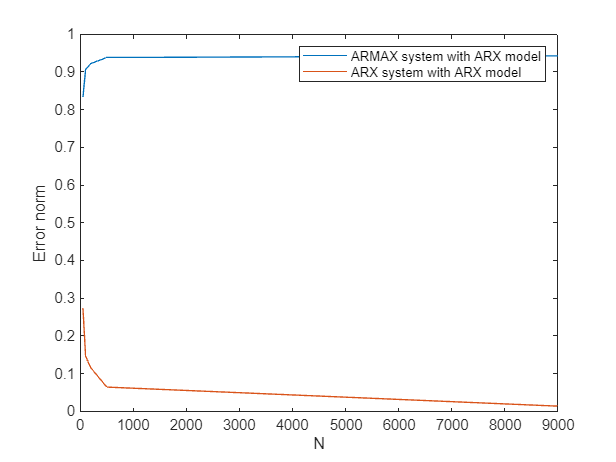

% Splits considered
index = [50, 100, 200, 500, 9000];

% Plotting results
figure(1),
plot(index,avg1,index,avg2),
xlabel("N"), ylabel("Error norm"),
legend("ARMAX system with ARX model","ARX system with ARX model");

### 3.2. Understanding results

We can see that when the system is identified with the right model (in orange), the error decreases as the number of available data increases. Instead, when the system is identified with the wrong model (in blue), the error is not a strictly-decreasing function.

We can easily understand, by looking at the blue plot, that we did something wrong during the identification process because there is a peak and then an increase, which is an odd and undesired behaviour when increasing the number of available data.

## 4. Studying polarization with respect to noise variance

Let us now consider the case where we identified an ARMAX system with an ARX model, so by choosing the wrong model. We want to assess how the results change with respect to the variance of the noise.

### 4.1. Generating the system to identify

First we define the vectors containing the noise variances to be considered and the number of available data, respectively. 

% Noise variances
vars = [0, 10e-9, 10e-7, 10e-5, 10e-4];

% Splits considered
index = [50, 100, 200, 1000, 9500];

We also set a fixed number of iterations in order to stabilize the behaviour of the noise.

% Iterations
iters = 50;

We choose the sampling time, we create the time vector and we retrieve the maximum dimension of data.

% Sampling time
Ts = 0.01;

% Time vector
t = (0:Ts:(10000*Ts))';

% Data dimension
Nmax = length(t);

Then we generate the system we want to identify using the `zpk` function, which return the continuous transfer function of the system by giving in input the zeros, the poles and the static gain of the system.

% Continuous transfer function
G = zpk(10, [-20, -20, -50, -100], -400*50*10);

Since the data acquisition process is discrete, we need to discretize the transfer function of the system.

% Discretization of the transfer function
Gz = c2d(G,Ts);

Let's see how the discrete system behaves through its impulse response.

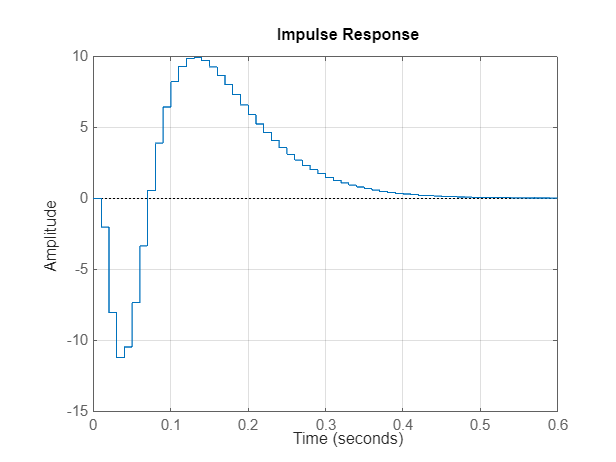

% Impulse response
figure(2), impulse(Gz), grid;

Let's also see how the discrete system behaves through its step response.

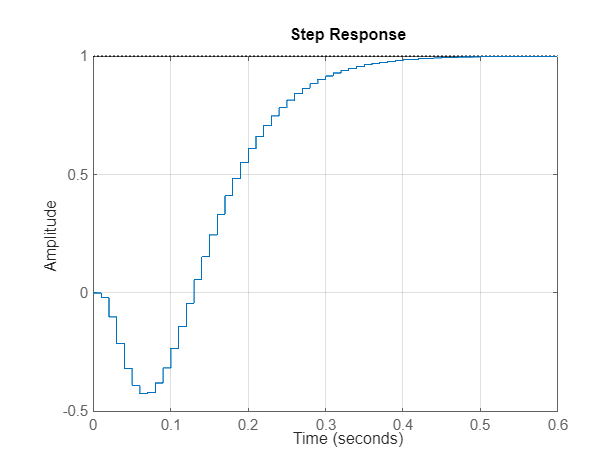

% Step response
figure(3), step(Gz), grid;

### 4.2. Tweaking the parameters of the system

We extract the numerator and denominator polynomials from the transfer function using the command `tfdata`.

% Extracting coefficients
[num,den] = tfdata(Gz,'v')

num =          0   -0.0204   -0.0273    0.0476    0.0083


den =     1.0000   -2.6119    2.4890   -1.0185    0.1496


Then we tweak the parameters of the system rounding them up in order to better appreciate the quality of the estimates.

% Rounding coefficients
A = [1.00, -2.62,  2.49, -1.02, 0.15];
B = [0.00, -0.02, -0.03,  0.05, 0.01];
C = [1.00,  1.90,  0.40];

Since we also have the polynomial `C`, we are generating an ARMAX system.

### 4.3. Extracting data from the system

Since we are interested in studying the behaviour of the estimation error with respect to the different variances of the noise, we use a first `for` loop. Then, since we are working with random values, we use a second `for` loop in order to stabilize the noise.

% First loop
for i=1:length(vars)

    % Initialization
    error = [];

    % Second loop
    for j=1:iters

We need to extract from the system the data that we actually want to analyze. To do so we create a random vector of inputs, in order to stimulate the system, and a random vector of errors.

        % Random inputs
        U = randn(Nmax,1);
    
        % Random errors
        E = randn(Nmax,1);

Then we use the `idpoly` function in order to declare a polynomial model with identifiable parameters, using the polynomials of the previously-tweaked system. MATLAB will automatically recognize the ARX model and all its parameters.

        % System declaration
        S = idpoly(A,B,C,[],[],vars(i),Ts);

Now we can finally simulate the behaviour of the system given the random input vector and the random error vector.

        % Output vector
        Y = sim(S,[U,E]);

### 4.4. Splitting data in multiple sets

Since we now have our input and output measurement data, we can go on with the identification of the system.

We first create our `iddata` object, giving labels to the input and to the output.

        % Creating data object
        data = iddata(Y,U,Ts);

Then we perform some splits for the training set varying the number of available data.

        % Training sets
        train50   = data(1:50);
        train100  = data(1:100);
        train200  = data(1:200);
        train1000 = data(1:1000);
        train9500 = data(1:9500);
    
        % Validation set
        validation = data(9501:10000);

### 4.5. Identifying the system using ARX models

Let's declare different ARX models, one for each of the previously-splitted training sets.

        % ARX(4,4,1) models
        m50   = arx( train50,[4,4,1]);
        m100  = arx( train100,[4,4,1]);
        m200  = arx( train200,[4,4,1]);
        m1000 = arx(train1000,[4,4,1]);
        m9500 = arx(train9500,[4,4,1]);

Then we extract the numerator and the denominator of each of the identified models.

        % Numerators and denominators
        [  B50,   A50] = tfdata(  m50,'v');
        [ B100,  A100] = tfdata( m100,'v');
        [ B200,  A200] = tfdata( m200,'v');
        [B1000, A1000] = tfdata(m1000,'v');
        [B9500, A9500] = tfdata(m9500,'v');

### 4.6. Computing the estimation errors

We use these vectors to compute the error as the maximum of the norms.

        % Error
        e50   = max([  norm(B50-B),   norm(A50-A)]);
        e100  = max([ norm(B100-B),  norm(A100-A)]);
        e200  = max([ norm(B200-B),  norm(A200-A)]);
        e1000 = max([norm(B1000-B), norm(A1000-A)]);
        e9500 = max([norm(B9500-B), norm(A9500-A)]);

For the sake of simplicity we group all the errors in one vector

        e = [e50, e100, e200, e1000, e9500];

and save them in a structure that will contain the vectors computed at each of the 20 iterations.

        errors = [errors; e];
    end

Then we compute the average error for each case using the `eval` function.

    eval(strcat("avg", num2str(i), " = mean(errors,1)"));
end

avg1 =     0.0779    0.0417    0.0329    0.0184    0.0040


avg2 =     0.0482    0.0264    0.0205    0.0114    0.0026


avg3 =     0.0537    0.0341    0.0288    0.0193    0.0137


avg4 =     0.3054    0.2902    0.2984    0.2931    0.2932


avg5 =     0.6101    0.6003    0.6020    0.5933    0.5929


### 4.7. Plotting results

Finally we can plot the behaviour of the average noises against the indexes for each of the variances of the noise.

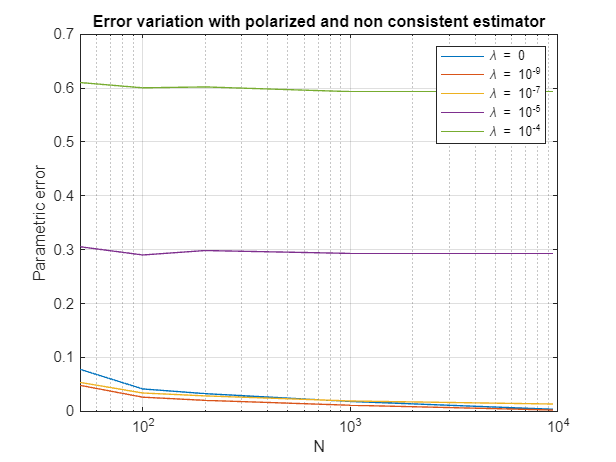

% Plotting results
figure(4),
semilogx(index,avg1,index,avg2,index,avg3,index,avg4,index,avg5), grid,
legend("\lambda = 0","\lambda = 10^{-9}","\lambda = 10^{-7}","\lambda = 10^{-5}","\lambda = 10^{-4}"),
title("Error variation with polarized and non consistent estimator"),
xlabel("N"), ylabel("Parametric error");

As we can see, when the variance of the noise is equal to zero (no uncertainty), we are in an ideal case where, no matter what happens, the error will go down. As the variance of the error increases, the error tends do assume a non-strictly decrescent behaviour. In fact, it does not always decrease when increasing the number of available data, but sometimes increases.